# Structural Brain Scan

Setup: I strongly suggest that you set this up so that you are using "Output inline", which makes the figures appear below instead of on the right (there should be a little toggle picture on the right side of this code). You may also want to "Undock" this notebook in order to get a better view by maximizing the notebook. You can undock by right-clicking on the tab at the top of the notebook.

We'll start by looking at a structural scan of the prettiest brain in the whole world. You'll need to make sure the brainimagingdata.mat file is in the same folder as this code (or in your path).

clear
load brainimagingdata.mat

## T1 Scan - Structural Scan of Whole Head

This code makes a little video at an angle called the coronal view. This starts from the back of the head and moves forward through to the eyes.

This code will loop through each "slice" and play a little video. If you switch aroudn with dimension of t1 the code loops through, you can see things from a different perspective (e.g., change t1(:,i,:) to t1(i,:,:) ).

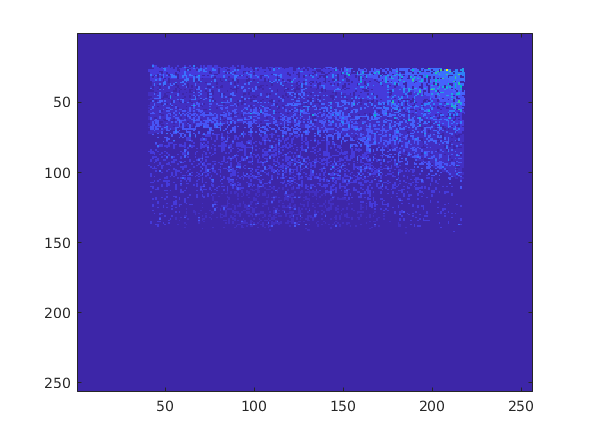

figure
for i = 1:256
    imagesc(rot90(squeeze(t1(:,:,i))));
    pause(.05);
end

## Sagital view of just the brain

Now we'll just look at the brain, without including the rest of the head.  You should be able to use the little slider below to move through different "slices" of the brain.

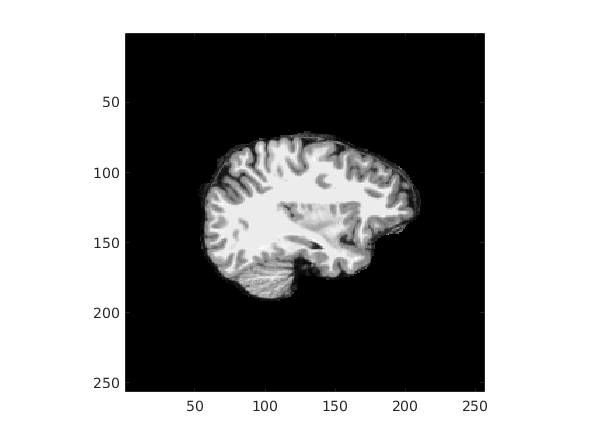

x = 160;
figure; colormap("gray"); imagesc(rot90(squeeze(brain(x,:,:)))); axis square;

## Coronal view of just the brain

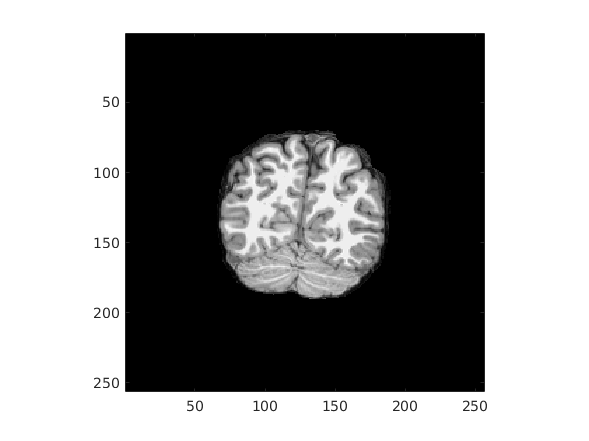

y =86;
figure; colormap("gray"); imagesc(rot90(squeeze(brain(:,y,:)))); axis square;

## Axial view of just the brain

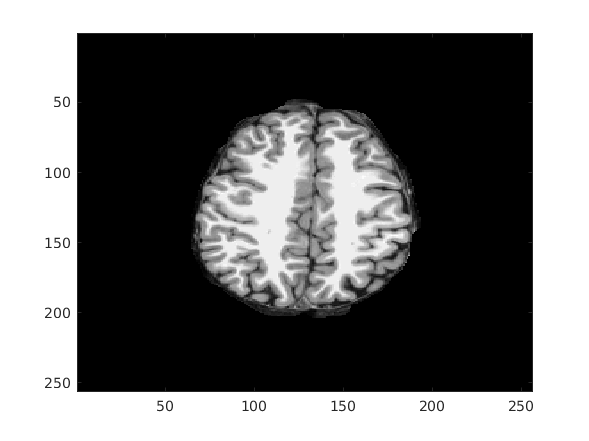

z = 158;
figure; colormap('gray'); imagesc(rot90(squeeze(brain(:,:,z))));

## White matter

The "white matter" refers to all of the axons and other cells that connect different parts of the brain. You can write your own code below to check out the white matter. You don't need to include a slider.

Sagital View of white matter

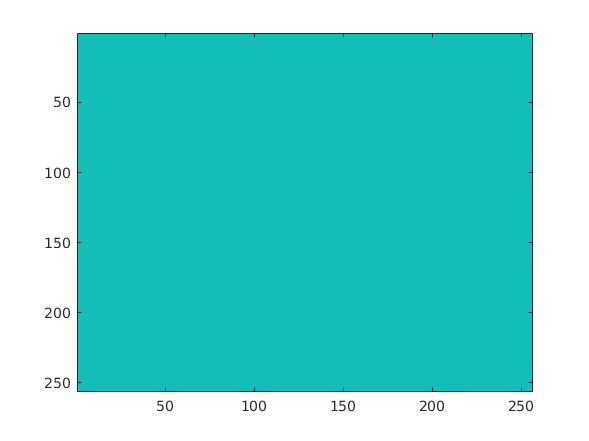

figure
for i = 1:256
    imagesc(rot90(squeeze(whitematter(:,:,i))));
    pause(.05);
end

Sagital View of white matter

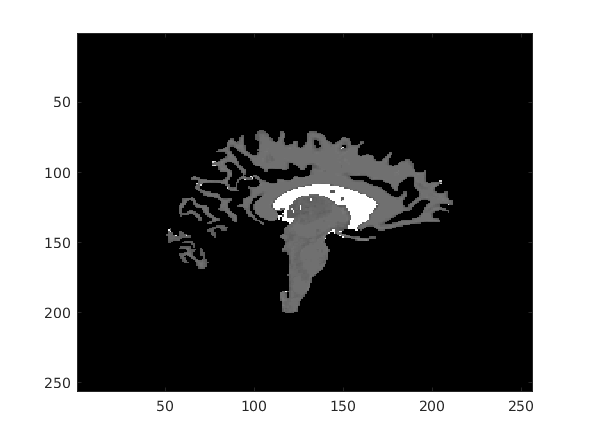

x = 121;
figure; colormap('gray'); imagesc(rot90(squeeze(whitematter(x,:,:))));

Coronal View of White Matter

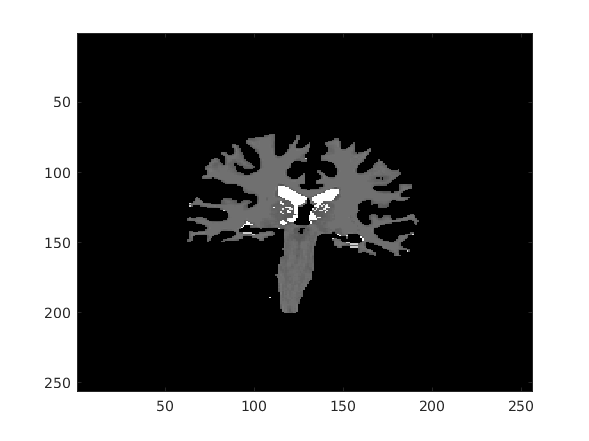

y = 121;
figure; colormap('gray'); imagesc(rot90(squeeze(whitematter(:,y,:))));

Axial View of White Matter

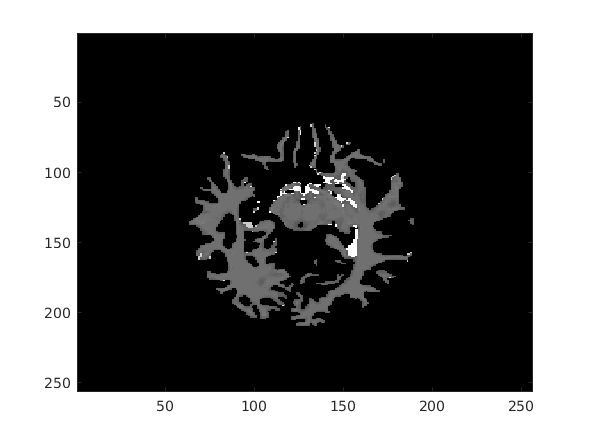

z = 114;
figure; colormap('gray'); imagesc(rot90(squeeze(whitematter(:,:,z))));

## Brain regions

There are lots of ways to divide the brain up into different regions. There's also still debate in the field of neuroscience about how much different regions have specific functional purposes versus how much every part of the brain in general (like most debates like this, the truth probably lies somewhere in between). 

One strategy that neuroscientists use in fMRI experiments is to look at the activation in a specific brain region. In order to do this, we need to identify the regions. This can be done using the anatomy of the brain or through something called a "functional localizer", in which we define a brain area based on a mix of anatomy and its "activity" during one task... and then measure it's activity during another task. I used the "functional localizer" strategy in this paper: [https://www.cell.com/neuron/pdfExtended/S0896-6273(15)00670-4](https://www.cell.com/neuron/pdfExtended/S0896-6273(15)00670-4) (You don't actually need to read this paper, just sharing for fun.)

In this code, you can pan through the brain and see different anatomical brain regions represented by different colors.

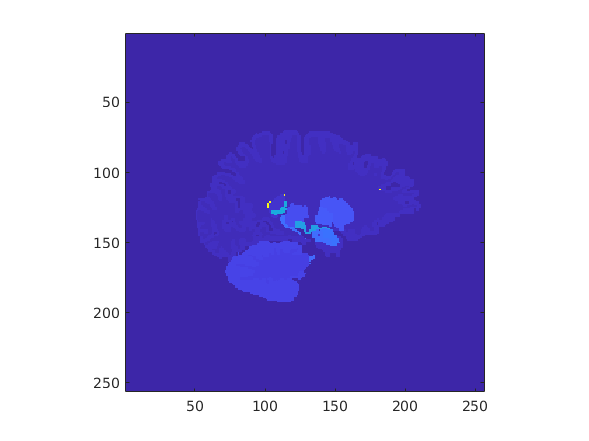

figure
x = 109;
bl= imagesc(rot90(squeeze(labelsbrain(x,:,:)))); axis square; 

## functional MRI data

We are going to now look at a different data set for some fMRI.

clear
load('fmriregions.mat')

Now we'll take a peek at some functional MRI data. The intention here is not to do any analysis, just to see what these data look like. We'll actually be using a version of this in our next machine learning assignment.

fMRI data is 4 dimensional: 3 dimensions of space and 1 dimension of time. 

This code makes a little video that shows the fMRI data for a slice of the brain at different time points. You can alter the code below to look at different places in the brain.

The dimensions of train_fmri3d are (x,y,z,time).

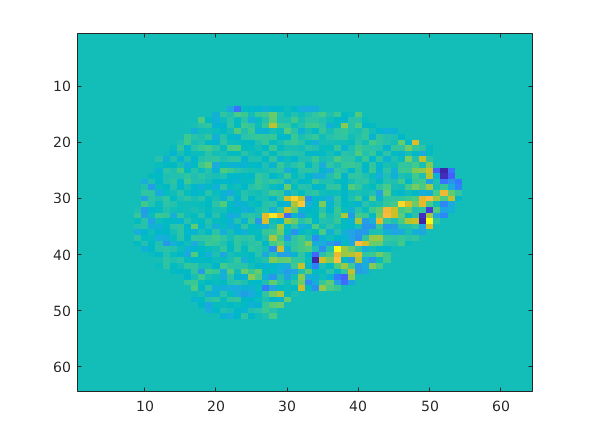

figure
for i = 1:162
    imagesc(rot90(squeeze(train_fmri3d(28,:,:,i))));
    caxis([-100 100]);
    pause(.05);
end

## Masks and regions

When looking at the fMRI data, researchers will constrain their view to only look in the parts of the 3d image that includes the brain (we don’t care about the blood flow to your skull). This is done by creating a “mask”, which is a binary volume where 1=brain and 0=not brain. 

The fMRI data above already is masked to only show values in the brain.  The code below will allow you to look at the mask of the brain and 4 "regions of interest".  To best view this 3d visualization, run the code below, which will pop the figure out (so it won't be "inline" below). Click on the brain, then click the little rotate3d button (blue arrow below).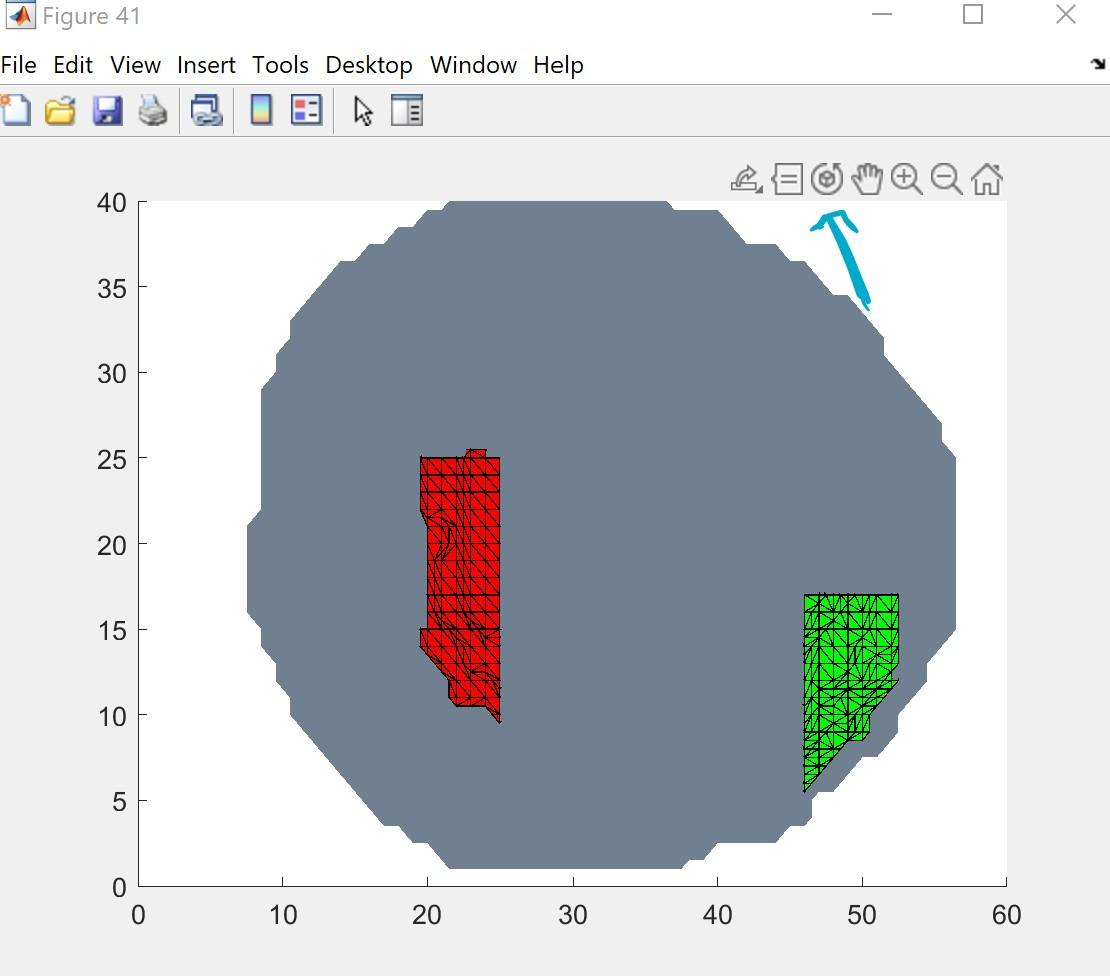

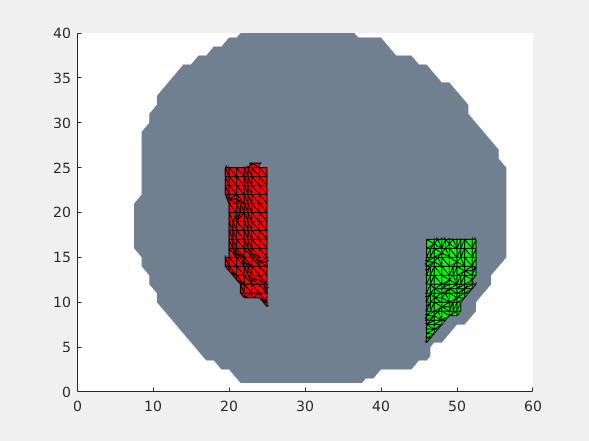

% Create a 3d figure of the surface of the brain
figure; set(gcf,'Visible','on');
[fo,vo] = isosurface(mask);  
p0 = patch('Faces', fo, 'Vertices', vo);  % draw the outside of the volume
p0.FaceColor = '#708090';
p0.EdgeColor = 'none';
hold on;
% Add region 1
[fo,vo] = isosurface(mask_region1); 
p1 = patch('Faces', fo, 'Vertices', vo); p1.FaceColor = 'green';
% Add region 2
[fo,vo] = isosurface(mask_region2); 
p2 = patch('Faces', fo, 'Vertices', vo); p2.FaceColor='red';
% Add region 3
[fo,vo] = isosurface(mask_region3); 
p3 = patch('Faces', fo, 'Vertices', vo); p3.FaceColor = 'blue';
[fo,vo] = isosurface(mask_region4); 
p4 = patch('Faces', fo, 'Vertices', vo); p4.FaceColor = 'cyan';

What you should see, is 4 different colored regions that appear in different places on a gray blob that is roughly brain-shaped. 

## Extracting average activity for different regions

Researchers often want to look at the average "activity" in different brain regions. In order to do that, we can index our train_fmri3d data to just look at the values for a particular region.

In order to do this, we need to smoosh the dimensions of things (you don't need to worry about the details of this).

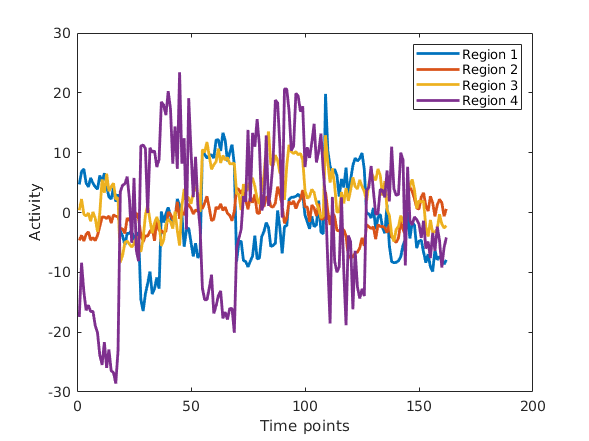

fmri2d= squeeze(reshape(train_fmri3d,1,1,[],162))';
r1mask2d=reshape(mask_region1,1,[]);
r2mask2d=reshape(mask_region2,1,[]);
r3mask2d=reshape(mask_region3,1,[]);
r4mask2d=reshape(mask_region4,1,[]);

%Create a variable that is the activity in each voxel of each region over
%time
r1vals = fmri2d(:,r1mask2d==1);
r2vals = fmri2d(:,r2mask2d==1);
r3vals = fmri2d(:,r3mask2d==1);
r4vals = fmri2d(:,r4mask2d==1);

% Find average in each region
r1avg = mean(r1vals,2);
r2avg = mean(r2vals,2);
r3avg = mean(r3vals,2);
r4avg = mean(r4vals,2);

figure
plot([r1avg, r2avg, r3avg,r4avg], 'LineWidth',2);legend({'Region 1','Region 2','Region 3','Region 4'});
xlabel('Time points'); ylabel('Activity')

This plot shows the average "activity" in each of our 4 brain regions at 162 different time points. Next class, we'll talk about what was happening at those different time points and use this to begin classifying brain activity using machine learning.